**Transient Diffusion-Reaction Model for Carbon Dioxide Electrolysis**

This model is based on the following works and adapted for the current format of interactivity:

- Gupta et al. *J. Appl. Electrochem. ***2006**, 36, 161–172

- Resasco et al. *ChemElectroChem*** 2018**, 5, 1064–1072

- Kas et al. *ChemElectroChem* **2015**, 2, 354–358

The following parameters may be altered to study its effect on the concentration profiles, pH, and explore the mass-transfer limiting current conditions:

T           =18 ; % temperature [degC]
P           =1 ; % pressure [bar]
j           =     -5  ; % current density [mA/cm2]
n_CO        =0.9; % CO Faradaic efficiency [-]
n_iHCOO     =0; % HCOO(-) Faradaic efficiency [-]
n_CH4       =0; % CH4 Faradaic efficiency [-]
n_C2H4      =0; % C2H4 Faradaic efficiency [-]
n_C2H5OH    =0; % C2H5OH Faradaic efficiency [-]
n_iCH3COO   =0; % CH3COO(-) Faradaic efficiency [-]
n           = [n_CO n_iHCOO n_CH4 n_C2H4 n_C2H5OH n_iCH3COO];

electrolyte = "KHCO3"      ;
c           =100; % concentration of electrolyte [mM]
L           =50; % diffusion boundary layer length [um]

Additional parameters for the numerical modelling algorithm:

n_x         = 101;       % number of grid points (must be odd-numbered)
t           = 10;       % total time of simulation [s]
dt          = 0.1;       % time step size [s]
simplified  = false;                        % ignore volumetric reaction terms that are small

Hit the button below when settings are as desired:

***1D Transient Diffusion-Reaction Model for CO2 Electrolysis***


---PART I: Thermodynamic and Kinetic Parameters---

Thermodynamic state of the system:
	 T = 291.15 K
	 P = 1.00 bar
	 c = 100.00 mol/m3 KHCO3
	 u = 1.07 mPa s (based on salt molarity and temperature)
	 p = 1004.9 kg/m3 (based on salt molarity)
Solubility of CO2 in equilibrium with 1.00 bar pure CO2 atmosphere:
	 40.0 mM (Henry Law)	 --->	 38.6 mM (Sechenov)
Diffusion coefficients of species in the diffusion layer:
	 D(CO2)     = 1.553e-09 m2/s
	 D(HCO3(-)) = 9.636e-10 m2/s
	 D(CO3(2-)) = 7.506e-10 m2/s
	 D(OH(-))   = 4.288e-09 m2/s
	 D(H(+))    = 7.571e-09 m2/s
Corrected for temperature and viscosity.

Self-ionization constant of water:
	 Kw         = 5.814e-15 M2 (pKw = -log(Kw) = 14.24)
Note that Kw is only corrected for temperature, not ionic strength.

Equilibrium coefficients:
	 Ka1        = [HCO3(-)][H(+)] /[CO2]     = 7.309e-07 M (pKa1 = 6.14)
	 Ka2        = [CO3(2-)][H(+)] /[HCO3(-)] = 2.492e-10 M (pKa2 = 9.60)

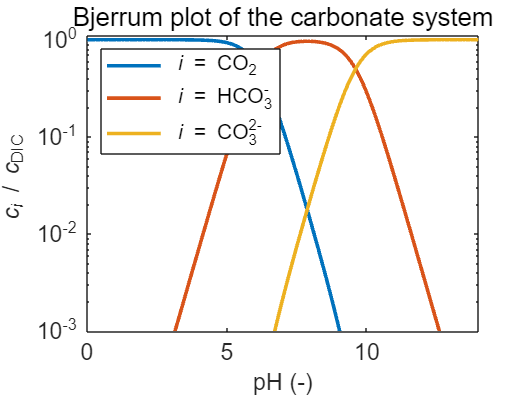


Fraction of CO2/HCO3(-)/CO3(2-) of Dissolved Inorganic Content (DIC) as function of pH.

The initial conditions of the CO2-saturated electrolyte are:
	CO2     38.60482 mM
	OH(-)   0.00002 mM
	HCO3(-) 99.82427 mM
	CO3(2-) 0.08800 mM
	H(+)    0.00028 mM
	pH      6.55 

Elapsed time for PART II is 1.498 seconds.


---PART III: Transient and Stabilized Solution Profiles---

Model parameters:
	diffusion boundary layer thickness     50.00 um
	logarithmic grid spacing               101 points
	minimum step size at edge              0.00017 um
	total modelling time                   10.00000 s
	time step size                         0.10000 s

For j = -5.0 mA/cm2 and n_CO = 0.90, the mass-transfer limiting current density is estimated as -25.7 mA/cm2.

Elapsed time for PART III is 1.289 seconds.



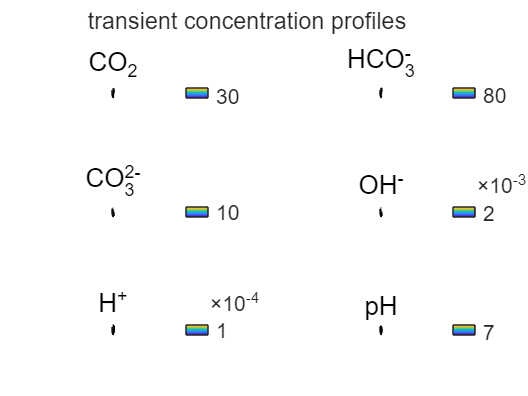

The transients upon imposing -5.0 mA/cm2 at the cathode.


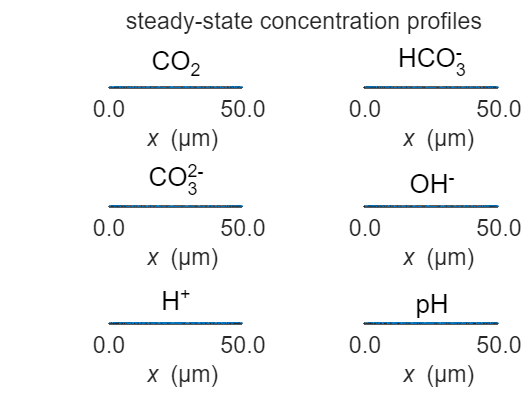

The profiles 10.0 s after imposing -5.0 mA/cm2 at the cathode.

Concentrations at the cathode surface after equilibration:
	CO2     29.61928 mM
	HCO3(-) 77.74580 mM
	CO3(2-) 31.48082 mM
	OH(-)   0.0098138901 mM
	H(+)    0.0000006157 mM
	pH      9.21   


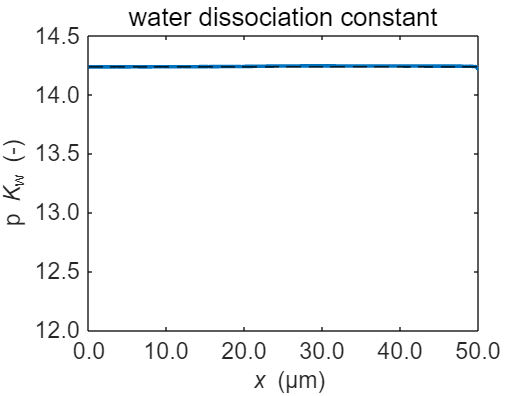

The calculated water dissociation constant compared to the theoretical value (dashed).

Elapsed time for PART IV is 1.084 seconds.


***Total elapsed time for this script is 4.080 seconds.***

 

% make call to model script using above parameters
tdr_model(T,P,j,n,electrolyte,c,L,n_x,t,dt,simplified);